# 6.4 设计Chebyshev数字带阻滤波器

## 6.4 利用双线性z变换法设计50Hz的Chebyshev数字带阻滤波器：   

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------
clear all;

fp=[44 56];fs=[47 53];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
rp=3;rs=50;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap =   278.2345  355.5340


was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0         0         0    0.0313


a =     1.0000    0.5707    1.6628    0.6906    0.6991    0.1634    0.0442


bw=wap(2)-wap(1)

bw = 77.2995

w0=sqrt(wap(1)*wap(2))

w0 = 314.5184

[bt,at]=lp2bs(b,a,w0,bw)

bt = 	1.0e+29 *

    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0004   -0.0000    6.6337


at = 	1.0e+29 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0007    0.0270    9.3703


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 =     0.6089   -6.9539   36.7445 -118.7534  261.3934 -412.7774  479.4758 -412.7774  261.3934 -118.7534   36.7445   -6.9539    0.6089


az1 =     1.0000  -11.1145   57.1903 -180.1085  386.5896 -595.7513  675.8540 -568.7217  352.3334 -156.7382   47.5337   -8.8256    0.7589


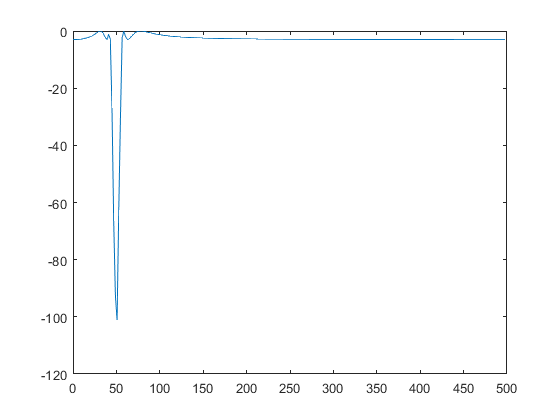

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))